# Sensing System - Performance Evaluation

## Initialize the Evaluation Script

clear;
%generate a random seed based on the date and time of day
c = clock;
seed = floor(sum(c));
rng(seed);
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
file_path = "20MHz_USRP.json";
% file_path = "20MHz_USRP_revA.json";
% file_path = "100MHz.json";

config_path = david_path + file_path;

### Generate a test set parameters for evaluating performance

%specify maximum constraints
valid_chirp_periods = [400,500];
FMCW_BW_MHz = 25.00;
num_adc_samples = 256;
num_chirps = 128;
num_cases = 200;
frames_to_compute = 7;

[slopes,chirp_periods,adc_sampling_rates] = ...
    characterization_functions.USRP_initialize_sensing_subsystem_test_cases(num_cases, ...
                valid_chirp_periods, ...
                FMCW_BW_MHz, ...
                num_adc_samples);

[slopes, chirp_periods, adc_sampling_rates]  =...
    characterization_functions.USRP_check_test_configurations(slopes, ...
    chirp_periods, ...
    adc_sampling_rates, ...
    num_adc_samples, ...
    FMCW_BW_MHz, ...
    config_path);

4 configuration(s) failed 



num_cases = size(slopes,1);

### Save Configuration Chirps to a File

%save all configuration chirps to a file
chirp_save_file_path = "/home/david/Documents/MATLAB_generated/MATLAB_full_chirps/";
[testing_data_parameter_estimations, ...
testing_data_frame_start_prediction_errors] = ...
characterization_functions.USRP_save_test_case_chirps(num_cases, ...
                    frames_to_compute, ...
                    slopes, ...
                    chirp_periods, ...
                    adc_sampling_rates, ...
                    num_adc_samples,...
                    num_chirps, ...
                    config_path, ...
                    "USRP_test_data",...
                    chirp_save_file_path);

Unrecognized function or variable 'num_cases'.

### Run all of the test configurations and save results to a file

% slopes = slopes(1:13,:);
% chirp_periods = chirp_periods(1:13,:);
% adc_sampling_rates = adc_sampling_rates(1:13,:);
% num_cases = 13;

frame_period_ms = 100.00;
save_file_name = "USRP_test_data";
usrp_results_path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/";
testing_data_parameter_estimations = ...
                characterization_functions.USRP_get_test_case_results( ...
                    num_cases, ...
                    slopes, ...
                    chirp_periods, ...
                    adc_sampling_rates, ...
                    frame_period_ms, ...
                    save_file_name,...
                    usrp_results_path);

### Plot Configuration Informatoin

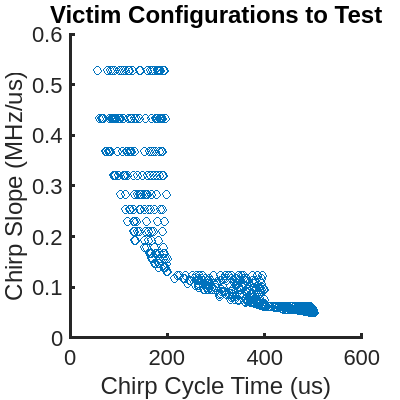

read_file_path = "USRP_test_data_parameter_estimations.csv";
characterization_functions.plot_test_configurations(read_file_path);

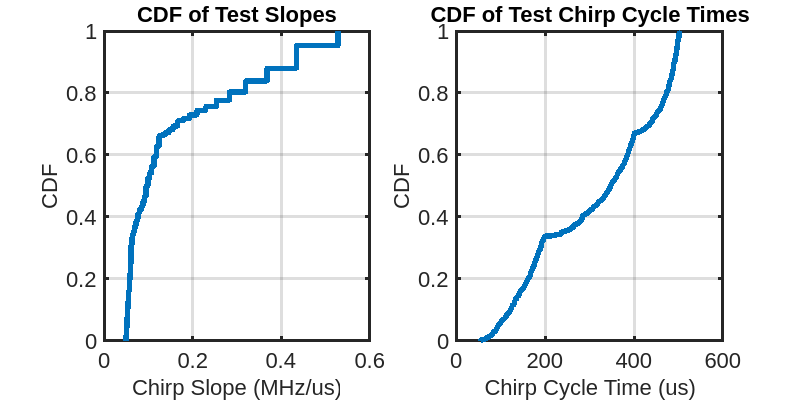

characterization_functions.plot_test_configuration_cdfs(read_file_path);

### Plot testing results

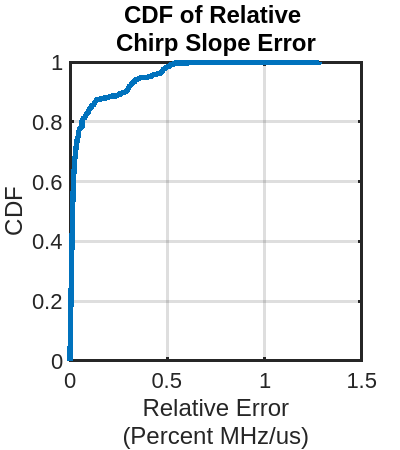

summary_table = 1×5 table
    Mean (MHz/us)    Variance (MHz/us)^2    MSE (MHz/us)^2    95th Percentile (MHz/us)    Percent Failed Trials
    _____________    ___________________    ______________    ________________________    _____________________

      0.065842            0.017282            5.0342e-07              0.40273                       0          


%plot the cdf of the chirp slope errors
read_file_path = "USRP_test_data_parameter_estimations.csv";
actual_values_idx = 1;
estimated_vals_idx = 5;
abs_errors_idx = 8;
metric_title = "Chirp Slope";
metric_units = "MHz/us";
percentile = 95;
scale_factor = 1;
summary_table = characterization_functions.generate_testing_summary_relative_error(...
    read_file_path,...
    actual_values_idx,...
    estimated_vals_idx,...
    abs_errors_idx,...
    metric_title,...
    metric_units,...
    percentile, ...
    scale_factor, ...
    true)

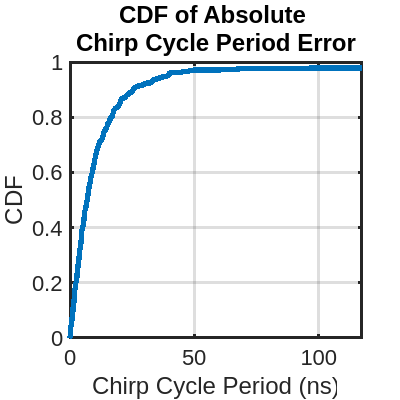

summary_table = 1×5 table
    Mean (ns)    Variance (ns)^2    MSE (ns)^2    95th Percentile (ns)    Percent Failed Trials
    _________    _______________    __________    ____________________    _____________________

     18.954          4654.5           5005.9             39.099                     0          


%chirp cycle period
read_file_path = "USRP_test_data_parameter_estimations.csv";
actual_values_idx = 2;
estimated_vals_idx = 6;
abs_errors_idx =9;
metric_title = "Chirp Cycle Period";
metric_units = "ns";
percentile = 95;
scale_factor = 1e3;
summary_table = characterization_functions.generate_testing_summary_absolute_error(...
    read_file_path,...
    actual_values_idx,...
    estimated_vals_idx,...
    abs_errors_idx,...
    metric_title,...
    metric_units,...
    percentile, ...
    scale_factor, ...
    true)

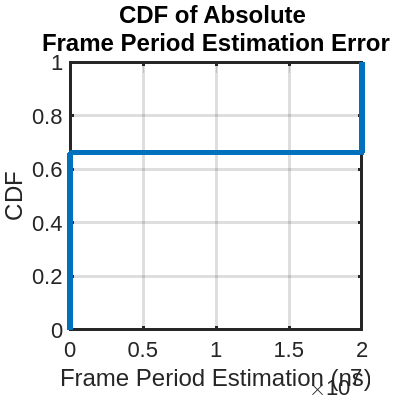

summary_table = 1×5 table
    Mean (ns)     Variance (ns)^2    MSE (ns)^2    75th Percentile (ns)    Percent Failed Trials
    __________    _______________    __________    ____________________    _____________________

    6.7685e+06      8.9701e+13       1.3536e+14           2e+07                      0          


read_file_path = "USRP_test_data_parameter_estimations.csv";
actual_values_idx = 3;
estimated_vals_idx = 7;
abs_errors_idx =10;
metric_title = "Frame Period Estimation";
metric_units = "ns";
percentile = 75;
scale_factor = 1e6;
summary_table = characterization_functions.generate_testing_summary_absolute_error(...
    read_file_path,...
    actual_values_idx,...
    estimated_vals_idx,...
    abs_errors_idx,...
    metric_title,...
    metric_units,...
    percentile, ...
    scale_factor, ...
    true)

## Evaluating Frame Estimation Error Accuracy

## NOT IMPLEMENTED AT THIS TIME

% read_file_path = "sensing_subsystem_test_data_frame_start_time_prediction_errors.csv";
% characterization_functions.plot_predicted_start_time_errors(read_file_path);